# Isosurface Annotation App

## Load in data

s = load('mri.mat');
data = squeeze(s.D);

% Create isosurface
isovalue = 40;
[faces, vertices] = isosurface(data, isovalue);
voxel_size  = [1 1 3];
vertices    = vertices .* voxel_size;
vertexNormals = isonormals(data,vertices);

% Place into an IsosurfaceModel
isoModel = wt.model.IsosurfaceModel(...
    'Faces',faces,...
    'Vertices',vertices,...
    'VertexNormals',vertexNormals);

## Create the app

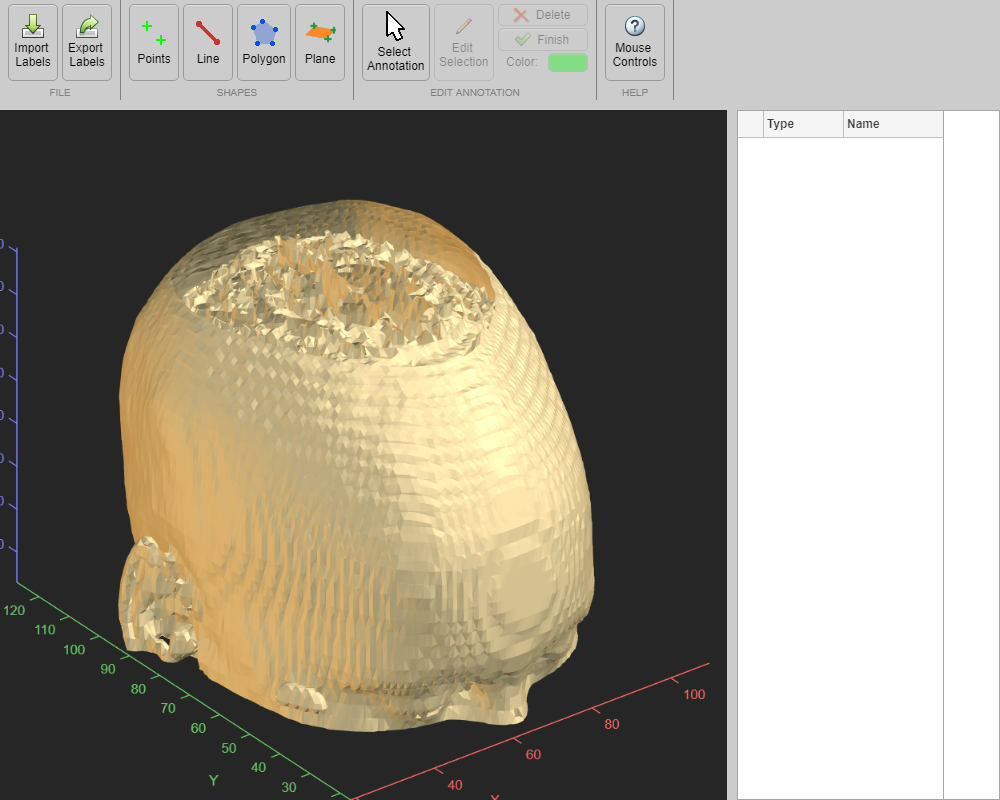

app = wt.apps.IsosurfaceAnnotationApp('IsosurfaceModel',isoModel);

## Add Starting Annotations

This is just for show, to make the screenshot of the app in action

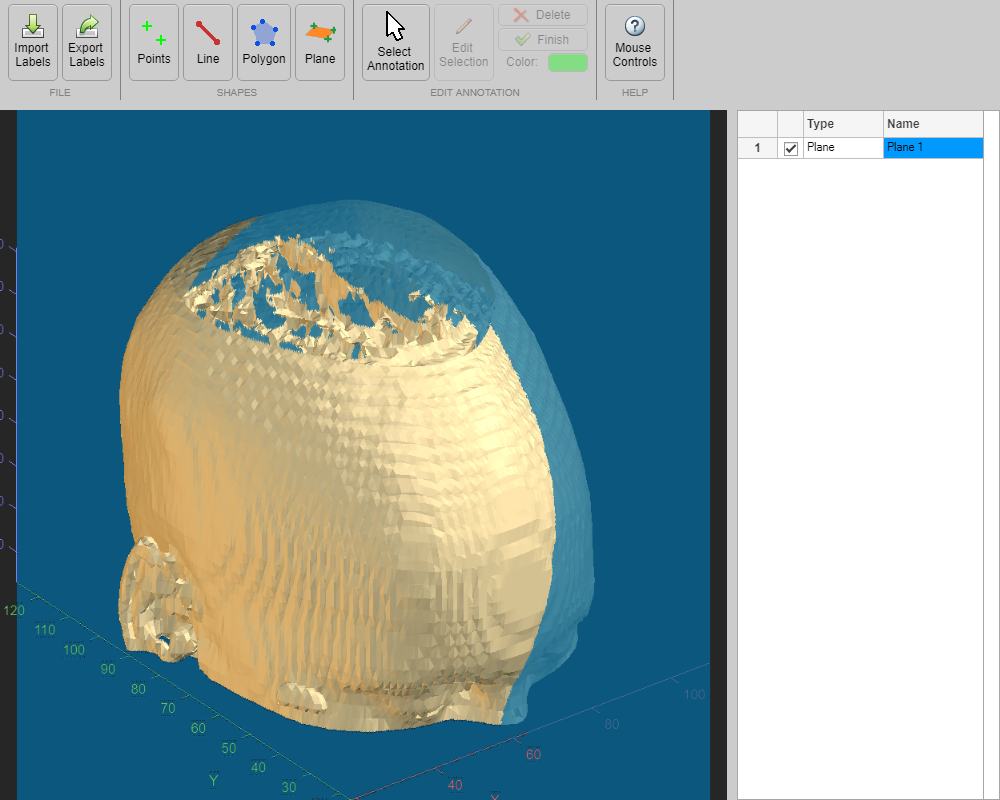

thisPoints = [
   110.6 67.67 77.12
   17.41 72.61 38.27
   20.97 64.07 4.049
   ];
thisColor = [0 0.6000 1];
thisAlpha = .7;
a1 = wt.model.PlaneAnnotation(...
    'Name','Plane 1',...
    'Points',thisPoints,...
    'Color',thisColor,...
    'Alpha',thisAlpha,...
    'IsVisible',true);

app.AnnotationViewer.addAnnotation(a1);

*Copyright 2018-2021 The MathWorks, Inc.*